clearvars; close all;
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\04_IV_curve_n2_maxb1.mat';
load(LPath)

CONVERSION_TO_J = 1000*100; % Conversion in mA over cm2

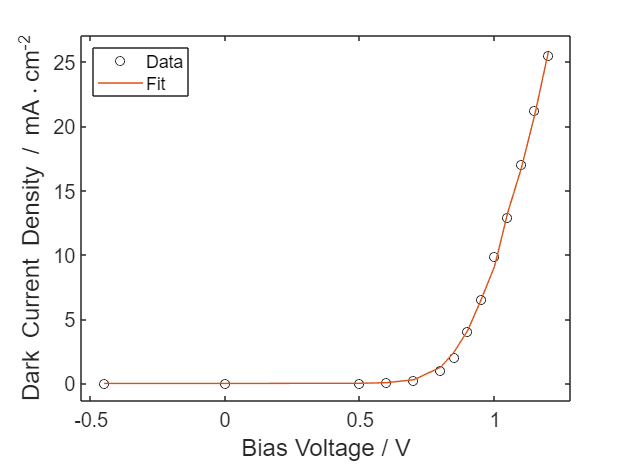

iBest = 3;
Is_ = bestFit.Is1(iBest);
Rs_ = bestFit.Rs(iBest);
Rsh_ = 30e16;
alpha_ = bestFit.alpha1(iBest);
Ifit = onediodemodel(V, I, [Is_, Rs_, Rsh_, alpha_]);
Ifit = Ifit;

figure()
tL = tiledlayout('flow');
nexttile;

plot(V, I*CONVERSION_TO_J, 'o', 'Color', 'black')
hold on
plot(V, Ifit*CONVERSION_TO_J, 'Color', '#D95319')

lgd = legendFirstTile(tL, {'Data', 'Fit'});
lgd.Location = "northwest";

xlim(setAxLim(V, 0.05));
ylim(setAxLim(Ifit*CONVERSION_TO_J, 0.05))
grid off
legendFirstTile(tL);
labelAxesFig(tL, "Bias Voltage / V", 'Dark Current Density / mA{\cdot}cm^{-2}')

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, 'IV chip on', '.png')

Graphics not exported


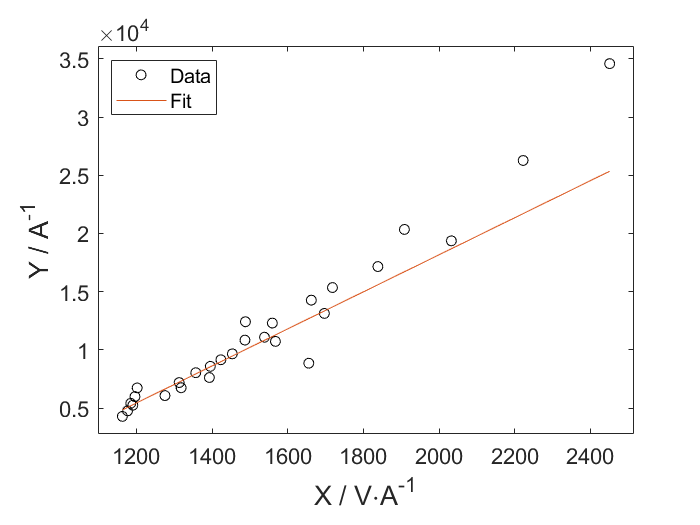

idxStart = 7;
nI = numel(I);
ny = (nI - idxStart + 1)*(nI - idxStart)/2;
[x, y] = deal(zeros(ny, 1)); 
iy = 1;
for i0 = idxStart:nI - 1
    I0 = I(i0);
    V0 = V(i0);
    for ii = i0 + 1:nI
        y(iy) = log(I(ii)/I0)/(I(ii)-I0);
        x(iy) = (V(ii)-V0)/(I(ii)-I0);
        iy = iy + 1;
    end
end

xDummy = linspace(min(x), max(x), 1000);
figure()
tL = tiledlayout('flow'); nexttile
plot(x, y, 'o', 'Color', 'black')
hold on
plot(xDummy, Fit1{iBest}.scale*Fit1{iBest}.pfit(1)*xDummy + Fit1{iBest}.scale*Fit1{iBest}.pfit(2))
xlim(setAxLim(x, 0.05))
ylim(setAxLim(y, 0.05))
labelAxesFig(tL, 'X / V{\cdot}A^{-1}', 'Y / A^{-1}');
lgd = legendFirstTile(tL, ["Data", "Fit"]);
lgd.Location = "northwest";
exportFig(gcf, Opt.SFolder, 'IV chip on_1', '.png')

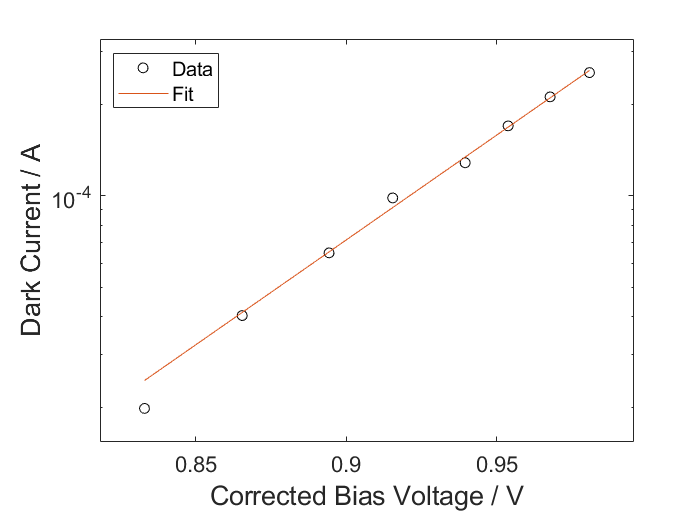

Rs_ = -Fit1{iBest}.pfit(2)/Fit1{iBest}.pfit(1);
Vc = V(idxStart:end) - I(idxStart:end)*Rs_; % Corrected voltage values
lnI = log(I(idxStart:end));

xDummy = linspace(min(Vc), max(Vc), 1000);
figure()
tL = tiledlayout('flow');
nexttile
semilogy(Vc, exp(lnI), 'o', 'Color', 'black')
hold on
semilogy(xDummy, exp( ...
    Fit2{iBest}.scale*Fit2{iBest}.pfit(1)*xDummy + Fit2{iBest}.scale*Fit2{iBest}.pfit(2)))
xlim(setAxLim(Vc, 0.1))
ylim(exp(setAxLim(lnI, 0.1)))
labelAxesFig(tL, 'Corrected Bias Voltage / V', 'Dark Current / A');
lgd = legendFirstTile(tL, ["Data", "Fit"]);
lgd.Location = "northwest";
exportFig(gcf, Opt.SFolder, 'IV chip on_2', '.png')

# RMSD plot

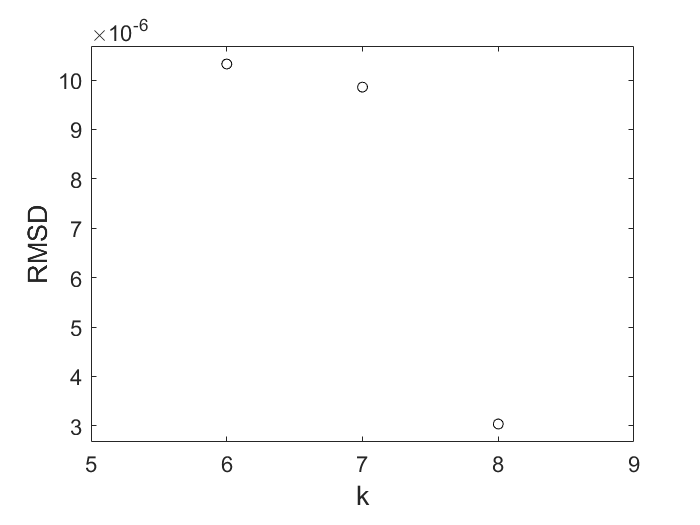

figure()
tL = tiledlayout('flow'); nexttile
plot(bestFit.IDX_START_INITIAL:bestFit.IDX_START_INITIAL + 2, bestFit.Rmsd(1:3), 'o', 'Color', 'black')
xlim([(bestFit.IDX_START_INITIAL - 1), (bestFit.IDX_START_INITIAL + 3)])
ylim(setAxLim(bestFit.Rmsd(1:3), 0.05))
labelAxesFig(tL, "k", "RMSD")
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, 'IV chip on RMSD vs k', 'png')

clearvars; close all;
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\04_IV_curve_n2_maxb1.mat';
load(LPath)

for ii = 1:numel(Fit1) - 3
    latexStrMat(1, ii) = sprintf("%i", (bestFit.IDX_START_INITIAL + ii - 1));
    latexStrMat(2, ii) = sprintf("$%.1f \\pm %.1f$", bestFit.alpha1(ii), bestFit.alpha1Std(ii));
    latexStrMat(3, ii) = sprintf("$%.2f \\pm %.2f$", bestFit.temp(ii), bestFit.tempStd(ii));
    latexStrMat(4, ii) = sprintf("$%.2f \\pm %.2f$", bestFit.Rs(ii)*1e-3, bestFit.RsStd(ii)*1e-3);
    latexStrMat(5, ii) = sprintf("$%.2f \\pm %.2f$", bestFit.Is1(ii)*1e12, bestFit.Is1Std(ii)*1e13);
    latexStrMat(6, ii) = sprintf("$%.3f$", bestFit.Rmsd(ii)*1e7);
    latexStr(ii) = strjoin(latexStrMat(:, ii), '    &     ');
    latexStr(ii) = strjoin([latexStr(ii), "\\"], '');
end
disp(strjoin(latexStr, '\n'))

6    &     $17.0 \pm 0.9$    &     $327.20 \pm 18.66$    &     $0.85 \pm 0.05$    &     $16.36 \pm 9.01$    &     $103.260$\\
7    &     $20.7 \pm 0.7$    &     $268.54 \pm 11.35$    &     $0.97 \pm 0.03$    &     $0.77 \pm 0.49$    &     $98.581$\\
8    &     $15.9 \pm 0.6$    &     $348.97 \pm 17.71$    &     $0.86 \pm 0.03$    &     $42.93 \pm 17.89$    &     $30.374$\\


latexStrMat(1, ii + 1) = "avg.";
latexStrMat(2, ii + 1) = sprintf("$%.2f \\pm %.2f$", mean(bestFit.alpha1), bestFit.alpha1Std(ii));
latexStrMat(3, ii + 1) = sprintf("$%.2f \\pm %.2f$", bestFit.n1(ii), bestFit.n1Std(ii));

Unrecognized field name "n1".

latexStrMat(4, ii + 1) = sprintf("$%.3f \\pm %.3f$", bestFit.Rs(ii)*1e-3, bestFit.RsStd(ii)*1e-3);
latexStrMat(5, ii + 1) = sprintf("$%.2f \\pm %.2f$", bestFit.Is1(ii)*1e13, bestFit.Is1Std(ii)*1e13);
latexStrMat(6, ii + 1) = sprintf("$%.3f$", bestFit.Rmsd(ii)*1e7);

function Ifit = onediodemodel(V, I, p)
    % p = [I0, Rs, Rsh, alpha]
    Idiode = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode + Ish;
end